# Interface Métodos Numéricos para ED/PVI

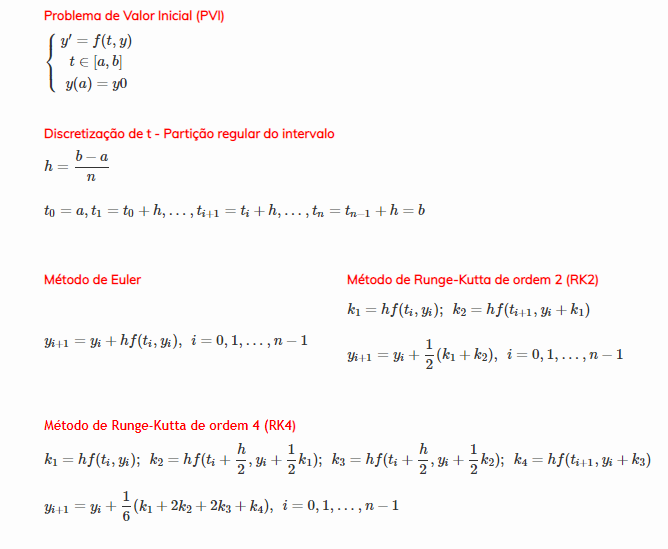

26/03/2021  -  

                 Arménio Correia           armenioc@isec.pt

19/04/2022 -

                Marinela Bettencourt    a2020110142@isec.pt

               Ana Silva                       a2021154586@isec.pt

               Pedro Serrano               a21260364@isec.pt

clear
syms y(t)

while 1
    strF = "-2*t*y";
    f =@(t,y) eval(vectorize(strF));
    try
        fTeste = f(t,y);
        break
    catch ME
        waitfor(errordlg("Introduza uma função em t e y","Erro"));
        break
    end
end

while 1
    a = -2;
    if (isscalar(a) && isreal(a)) 
        break
    else
        waitfor(errordlg("Introduza um valor real para a","Erro"))
    end
end

while 1
    b = 2;
    if (isscalar(b) && isreal(b) && b>a) 
        break
    else
        waitfor(errordlg("Introduza um valor real para b","Erro"))
    end
end

while 1
    n = 10;
    if (mod(n,1)==0 && isscalar(n) && n>0) 
        break
    else
        waitfor(errordlg("Introduza um valor inteiro maior que 0 em n","Erro"))
        break
    end
end

while 1
    y0 = 0.0549;
    if (isreal(y0) && isscalar(y0)) 
        break
    else
        waitfor(errordlg("Introduza um valor inicial","Erro"))
        break
    end
end

sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);

g =@(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);

 

disp('------------------------------Euler------------------------------- ')

------------------------------Euler------------------------------- 


yEuler = N_Euler(f,a,b,n,y0)

yEuler =     0.0549    0.1427    0.3254    0.6379    1.0461    1.3809    1.3809    0.9390    0.3380    0.0135   -0.0038


erroEuler = abs(yExata-yEuler)

erroEuler =     0.0000    0.0890    0.3847    0.9427    1.5081    1.6166    1.1734    0.6415    0.3721    0.2182    0.0587


tabela = [t.',yExata.',yEuler.',erroEuler.'];
array2table(tabela,"VariableNames",{'t','Exata','Euler','erroEuler'})

ans = 11×4 table
     t       Exata       Euler      erroEuler 
    ____    _______    _________    __________

      -2     0.0549       0.0549    6.9389e-18
    -1.6    0.23172      0.14274      0.088976
    -1.2    0.71018      0.32545       0.38473
    -0.8     1.5805      0.63788       0.94265
    -0.4     2.5542       1.0461        1.5081
       0     2.9974       1.3809        1.6166
     0.4     2.5542       1.3809        1.1734
     0.8     1.5805        0.939       0.64153
     1.2    0.71018      0.33804       0.37214
     1.6    0.23172     0.013522       0.21819
       2     0.0549    -0.003786      0.058686


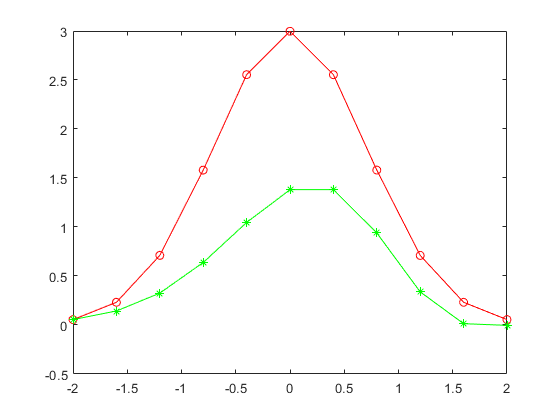

plot(t,yExata,"-ro")
hold on
plot(t,yEuler,"-g*")
hold off

disp(' ')

disp(' ')

disp(' ')


disp('------------------------------Euler Melhorado------------------------------- ')

------------------------------Euler Melhorado------------------------------- 


yEulerM = N_EulerM(f,a,b,n,y0)

yEulerM =     0.0549    0.1085    0.1859    0.2745    0.3474    0.3752    0.3452    0.2712    0.1836    0.1090    0.0584


erroEulerM = abs(yExata-yEulerM)

erroEulerM =          0    0.0043    0.0116    0.0200    0.0270    0.0304    0.0292    0.0234    0.0139    0.0038    0.0035


tabela = [t.',yExata.',yEulerM.',erroEulerM.'];
array2table(tabela,"VariableNames",{'t','Exata','EulerM','erroEulerM'})

ans = 11×4 table
     t       Exata      EulerM     erroEulerM
    ____    _______    ________    __________

      -2     0.0549      0.0549            0 
    -1.6    0.11279     0.10848     0.004306 
    -1.2    0.19746      0.1859      0.01156 
    -0.8    0.29457     0.27453     0.020039 
    -0.4    0.37447     0.34745     0.027025 
       0    0.40566     0.37524     0.030418 
     0.4    0.37447     0.34522     0.029249 
     0.8    0.29457     0.27121     0.023363 
     1.2    0.19746     0.18355     0.013903 
     1.6    0.11279     0.10896    0.0038316 
       2     0.0549    0.058401    0.0035008 


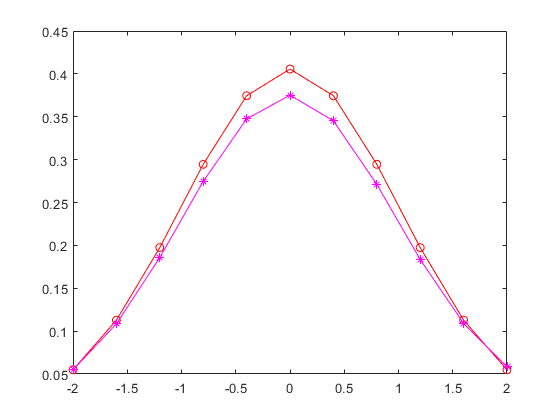

plot(t,yExata,"-ro")
hold on
plot(t,yEulerM,"-m*")
hold off

disp(' ')

disp(' ')

disp(' ')


disp('------------------------------RK2------------------------------- ')

------------------------------RK2------------------------------- 


yRK2 = N_RK2(f,a,b,n,y0)

yRK2 =     0.0549    0.1902    0.5200    1.0958    1.7339    2.0114    1.6896    1.0516    0.5334    0.2637    0.1540


erroRK2 = abs(yExata-yRK2)

erroRK2 =     0.0000    0.0415    0.1902    0.4848    0.8203    0.9861    0.8647    0.5289    0.1768    0.0320    0.0991


tabela = [t.',yExata.',yRK2.',erroRK2.'];
array2table(tabela,"VariableNames",{'t','Exata','RK2','erroRK2'})

ans = 11×4 table
     t       Exata       RK2       erroRK2  
    ____    _______    _______    __________

      -2     0.0549     0.0549    6.9389e-18
    -1.6    0.23172    0.19017      0.041543
    -1.2    0.71018    0.52001       0.19017
    -0.8     1.5805     1.0958       0.48476
    -0.4     2.5542     1.7339       0.82031
       0     2.9974     2.0114       0.98607
     0.4     2.5542     1.6896        0.8647
     0.8     1.5805     1.0516       0.52895
     1.2    0.71018    0.53336       0.17682
     1.6    0.23172    0.26369      0.031977
       2     0.0549      0.154      0.099097


plot(t,yExata,"-ro")
hold on
plot(t,yRK2,"-b+")
hold off

 

disp(' ')

disp(' ')

disp(' ')


disp('------------------------------RK4------------------------------- ')

------------------------------RK4------------------------------- 


yRK4 = N_RK4(f,a,b,n,y0)

yRK4 =     0.0549    0.1127    0.1972    0.2942    0.3739    0.4051    0.3739    0.2942    0.1972    0.1127    0.0550


erroRK4 = abs(yExata-yRK4)

erroRK4 = 	1.0e+-3 *

         0    0.1079    0.2553    0.4073    0.5244    0.5687    0.5257    0.4169    0.2685    0.0872    0.1040


tabela = [t.',yExata.',yRK4.',erroRK4.'];
array2table(tabela,"VariableNames",{'t','Exata','RK4','erroRK4'})

ans = 11×4 table
     t       Exata       RK4        erroRK4  
    ____    _______    ________    __________

      -2     0.0549      0.0549             0
    -1.6    0.11279     0.11268    0.00010793
    -1.2    0.19746      0.1972    0.00025534
    -0.8    0.29457     0.29416    0.00040735
    -0.4    0.37447     0.37395    0.00052439
       0    0.40566     0.40509    0.00056871
     0.4    0.37447     0.37394    0.00052567
     0.8    0.29457     0.29415    0.00041686
     1.2    0.19746     0.19719    0.00026846
     1.6    0.11279      0.1127    8.7157e-05
       2     0.0549    0.055004    0.00010397


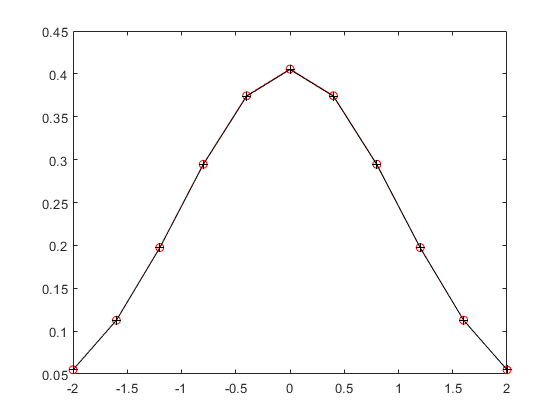

plot(t,yExata,"-ro")
hold on
plot(t,yRK4,"-k+")
hold off

disp(' ')

disp(' ')

disp(' ')


disp('------------------------------Ponto Médio------------------------------- ')

------------------------------Ponto Médio------------------------------- 


yPM = N_PM(f,a,b,n,y0)

yPM =     0.0549    0.1144    0.2021    0.3029    0.3857    0.4179    0.3858    0.3035    0.2025    0.1132    0.0517


erroPM = abs(yExata-yPM)

erroPM =          0    0.0016    0.0046    0.0084    0.0113    0.0123    0.0114    0.0089    0.0050    0.0004    0.0032


tabela = [t.',yExata.',yPM.',erroPM.'];
array2table(tabela,"VariableNames",{'t','Exata','PM','erroPM'})

ans = 11×4 table
     t       Exata        PM         erroPM  
    ____    _______    ________    __________

      -2     0.0549      0.0549             0
    -1.6    0.11279     0.11435     0.0015617
    -1.2    0.19746     0.20205     0.0045984
    -0.8    0.29457     0.30292     0.0083502
    -0.4    0.37447     0.38574      0.011269
       0    0.40566     0.41793      0.012273
     0.4    0.37447     0.38583      0.011364
     0.8    0.29457     0.30346     0.0088886
     1.2    0.19746     0.20247     0.0050114
     1.6    0.11279     0.11321    0.00042463
       2     0.0549    0.051654     0.0032459


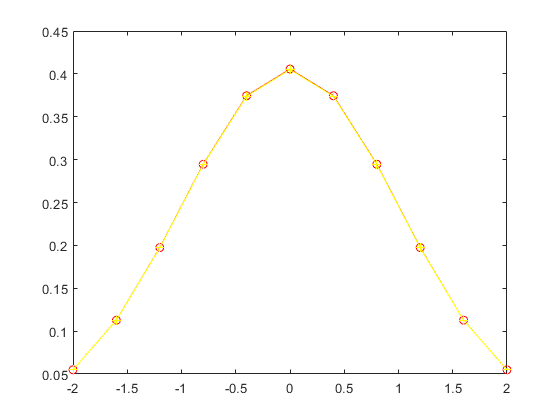

plot(t,yExata,"-ro")
hold on
plot(t,yRK4,"-y+")
hold off

disp(' ')

disp(' ')

disp(' ')


disp('------------------------------ODE45------------------------------- ')

------------------------------ODE45------------------------------- 


yODE45 = N_ODE45(f,a,b,n,y0)

yODE45 =     0.0549    0.1128    0.1975    0.2946    0.3745    0.4057    0.3745    0.2946    0.1975    0.1128    0.0549


erroODE45 = abs(yExata-yODE45)

erroODE45 = 	1.0e+-5 *

         0    0.1666    0.1732    0.1393    0.1669    0.2889    0.4281    0.4579    0.2618    0.1183    0.2049


tabela = [t.',yExata.',yODE45.',erroODE45.'];
array2table(tabela,"VariableNames",{'t','Exata','ODE45','erroODE45'})

ans = 11×4 table
     t       Exata      ODE45      erroODE45 
    ____    _______    ________    __________

      -2     0.0549      0.0549             0
    -1.6    0.11279     0.11279    1.6664e-06
    -1.2    0.19746     0.19746     1.732e-06
    -0.8    0.29457     0.29457    1.3933e-06
    -0.4    0.37447     0.37447    1.6689e-06
       0    0.40566     0.40566     2.889e-06
     0.4    0.37447     0.37447    4.2815e-06
     0.8    0.29457     0.29457    4.5787e-06
     1.2    0.19746     0.19746    2.6177e-06
     1.6    0.11279     0.11279     1.183e-06
       2     0.0549    0.054902    2.0487e-06


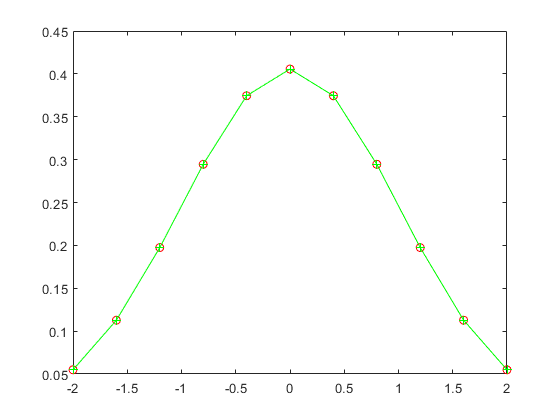

plot(t,yExata,"-ro")
hold on
plot(t,yODE45,"-g+")
hold off

disp(' ')

disp(' ')

disp(' ')


disp('------------------------------Todos------------------------------- ')

------------------------------Todos------------------------------- 



%Tabela com aproximações e erros
tabela = [t.',yExata.',yEuler.',yEulerM.',yPM.',yRK2.',yRK4.',yODE45.',erroEuler.',erroEulerM.',erroPM.',erroRK2.',erroRK4.',erroODE45.'];
array2table(tabela,"VariableNames",{'t','Exata','Euler','EulerM','PontoM','RK2','RK4','ODE45','erroEuler','erroEulerM','erroPontoM','erroRK2','erroRK4',erroODE45'})

ans = 11×14 table
     t       Exata      Euler       EulerM      PontoM       RK2         RK4       erroEuler    erroEulerM    erroPontoM     erroRK2      erroRK4       ODE45      erroODE45 
    ____    _______    ________    ________    ________    ________    ________    _________    __________    __________    _________    __________    ________    __________

      -2     0.0549      0.0549      0.0549      0.0549      0.0549      0.0549            0            0              0            0             0      0.05

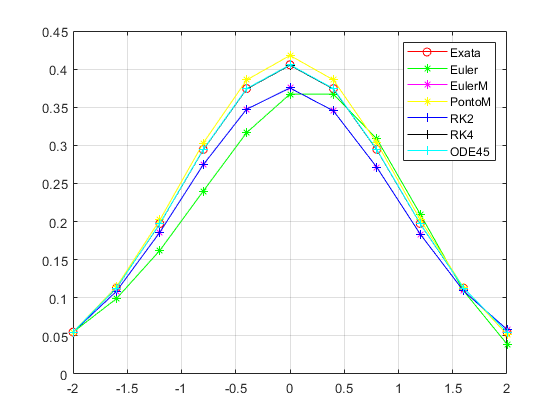


%Gráfico da exata e das aproximações
plot(t,yExata,"-ro")
hold on
plot(t,yEuler,"-g*")
plot(t,yEulerM,"-m*")
plot(t,yPM,"-y*")
plot(t,yRK2,"-b+")
plot(t,yRK4,"-k+")
plot(t,yODE45,"-c+")
hold off
grid on
legend('Exata','Euler','EulerM',"PontoM",'RK2','RK4','ODE45')